# **Exploring QAOA**

**Matteo Rossi**

## Section I - Enhancing MATLAB's QAOA with a Custom Class

### 1. QAOA Algorithm Description

The **Quantum Approximate Optimization Algorithm (QAOA)** is a hybrid quantum-classical algorithm designed to solve combinatorial optimization problems. Introduced by Farhi, Goldstone, and Gutmann in 2014, QAOA combines the potential of quantum circuits with classical optimization techniques to find high-quality approximate solutions for complex problems that are computationally challenging for classical computers.

**Hybrid Quantum-Classical Nature**

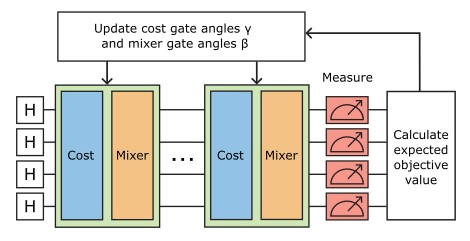

The algorithm operates in a feedback loop between quantum and classical systems: a parameterized quantum circuit prepares a quantum state that encodes potential solutions to the problem. A classical optimization algorithm iteratively adjusts the circuit's parameters to minimize (or maximize) the expected value of a cost function. This process leverages theoretical results of quantum mechanics to explore the vaste solution space efficiently while refining such parameters. 

**Mathematical Framework**

QAOA targets optimization problems formulated as Quadratic Unconstrained Binary Optimization (QUBO) problems. These are represented by a cost Hamiltonian $H_c$, whose ground state encodes the optimal solution.

- **Cost Hamiltonian**

            For a QUBO problem with $N$ binary variables $x_i \in \left\lbrace 0,1\right\rbrace$, the cost function is:

            
$$C\left(x\right)=\sum_i h_{i\;} x_i +\sum_{i<j} J_{\textrm{ij}} {\;x}_i {\;x}_j$$


            This maps to a quantum operator:

            $H_c =\sum_i h_{i\;} Z_i +\sum_{i<j} J_{\textrm{ij}} {\;Z}_i {\;\otimes \;Z}_j$, where $Z_i$ is the Pali-Z operator on *i-th* qubit.

- **Mixer Hamiltonian**

            The mixer $H_M$ drives transitions between quantum states. The most classical choices are:

            X Mixer: $H_M =\sum_i X_i$ (transverse field, promotes exploration

            XY Mixer: $H_M =\sum_{i<j} \left(X_i X_j +Y_i Y_j \right)$ (restricts transitions to feasible solution in constrained problems)

- **Parameterized Evolution**

            The QAOA circuit applies alternating layers of cost and mixer Hamiltonians:


$$|\psi \left(\gamma ,\beta \right)\rangle =\prod_{k=1}^p e^{-{\textrm{iB}}_k H_M } e^{-i\gamma_k H_C } \;|+\rangle^{\otimes N}$$
 

Here, $\gamma_k$ and $\beta_k$ are variational parameters optimized classically, and $p$ is the number of QAOA layers.

**Variational Principles**

The algorithm's success relies upon the **Variational Quantum Eigensolver (VQE)** framework:

- **Expectation Value: **The quantum device estimates $\langle \;\psi \;|{\;H}_{C\;} |\;\psi \;\rangle$, the average energy of the prepared state.

- **Classical Optimization: **A classical optimizer adjusts $\gamma ,\beta$ to minimize this energy.

- **Convergence: **After optimization, the final circuit is sampled to extract the msot probable solution.

**Applications to QUBO Problems**

QAOA is particularly suited for QUBO problems, which includes: Max-Cut and Knapsack (discussed later in the Live Script) and Logistic Optimization.

By encoding the problem into $H_c$, QAOA searches for low-energy states, i.e. solutions, through quantum superposition and interference. The number of layers $p$ balances solutions quality and circuit depth: higher $p$ balances solutions quality and circuit depth: higher $p$ improves approximation but increase noise susceptibility on near-term quantum devices.

### 2. Code Analysis of the QAOA Class

In this section, we present each property and method of the `QAOA` class in a clear manner. 

Before describing the code, a brief overview explains the role of each method in the QAOA workflow.

[**Class Properties**](matlab:open('./QAOA.m'))

**Which is the most suited optimizer for a problem?**

`1. fminsearch` (Nelder-Mead):

- **Use Case**: Small problems $\left(p\le 5\right)$ with smooth energy landscapes.

- **Strengths**: Fast, no gradient calculations.

- **Limitations**: Prone to local minima.

`2. fmincon`:

- **Use Case**: Medium-sized problems with parameter bounds (e.g. enforcing $\gamma \in \left\lbrack 0,\pi \right\rbrack$).

- **Strengths**: Handles constraints efficiently.

`3. surrogateopt`:

- **Use Case**: Rugged/noisy landscapes (common while choosing an high $p$) or when avoiding local minima is critical.

- **Strengths**: Global optimization, robust to noise.

- **Limitations**: Computationally expensive.

**Methods**

**NOTE: ***The following sections of code are not executable since they are not linked to a problem instance and extracted from the 'QAOA.m' class only to be explained.*

`solve()`**: Full QAOA Workflow**

The `solve` method executes the complete QAOA cycle: it prepares variational parameters, runs the classical optimizer, constructs the final circuit, and samples to determine a candidate solution.

- **Extract QUBO Terms     **Calls `extract_qubo_terms` to obtain the vectors `h` (linear biases) and matrix `J` (quadratic couplings).

- **Initialize Parameters      **Computes the total number of parameters `n_params = 2 * n_layers`, calls `initialize_parameters`, and converts them into a vector.

- **Define Bounds               **Sets lower bounds to 0 and upper bounds to π for all parameters.

- **Objective Function        **Objective Function `optimizer_objective` is wrapped in a function handle.

- **Classical Optimization  **Selects and runs the specified optimizer (`fminsearch`, `fmincon`, or `surrogateopt`) with the iteration budget.

- **Build Final Circuit          **Reshapes the optimized parameter vector back to a 2×n_layers array, constructs the circuit via `build_qaoa_circuit`, and plots it.

- **Sampling and Solution  **Simulates the circuit, draws `numShots` measurement samples, computes each sample’s energy, and selects the lowest‑energy bitstring.

- **Output                             **Returns a struct containing:

- `BestX`: the best bitstring

- `Energy`: its energy

- `OptimalParameters`: the final [γ;β] matrix

- `AllStates`: all sampled bitstrings

- `StateDistribution`: counts of each state

`optimizer_objective()`**: Energy Calculation**

It builds a new circuit at each execution with the provided parameters, simulates it and computes the expected energy.

**Steps**

- Reshape the parameter vector `p` into a 2×n_layers matrix of γ and β values.

- Build the trial circuit by calling `build_qaoa_circuit`.

- Simulate and sample the circuit `numShots` times.

- Convert the sampled states to binary vectors and compute each state’s energy via $x^T \;H\;x$.

- Return the expected energy.

`extract_qubo_terms(obj): ``Decompose Hamiltonian into Linear and Quadratic Components`

This helper separates the QUBO Hamiltonian into linear and quadratic components.

**Procedure**

- Symmetrize `H` by averaging it with its transpose. $\left(H+H^T \right)\cdot \frac{1}{2}$

- Extract the diagonal entries as the vector `h`.

- Extract the strictly upper‑triangular part as the matrix `J`.

Symmetry ensures the QUBO formulation **accurately represents the problem’s energy landscape** while avoiding redundancy.

In QUBO, the quadratic term $x_i {\;x}_j$ is **mathematically identical** to $x_j {\;x}_i$ (Commutative).

If the original matrix $H$ is **asymmetric** (e.g., $H_{\textrm{ij}} \not= H_{\textrm{ji}}$), the energy calculation ${\mathrm{x}}^{\mathrm{T}} \mathrm{H}\;\mathrm{x}$ would double-count the interactions.

**Example**: If $H_{12} =3$ and $H_{21} =1$, the term is $3x_1 x_2 +1x_2 x_1 =4x_1 x_2$.

Without symmetry, the solver treats $x_1 x_2$ and $x_2 x_1$ as distinct, leading to incorrect coefficients.

After symmetrizing HH, the upper-triangular part $J$ contains all unique quadratic terms; the lower triangle is discarded because it’s all redundant info.

`random_initialization(obj), ramp_initialization(obj):` **Parameter Initialization Strategy**

QAOA performance heavily depends on the initial values of parameters **γ (gamma)** and **β (beta)**. Below are the two implemented strategies, in case there's no prior knowledge to define a custom initalization:

**1. **`random_initialization(obj)`

The `random_initialization` strategy generates initial parameters by uniformly sampling γ from the interval [0, π] and β from [0, π/2]. 

This method prioritizes broad exploration of the  parameter space, making no assumptions about the problem’s structure. It is particularly useful in scenarios where prior knowledge of the energy landscape is limited or when testing QAOA on novel problems, as it avoids bias and encourages diverse sampling of potential solutions.

**2. **`ramp_initialization(obj)`

In contrast, the `ramp_initialization` strategy initializes γ with values linearly decreasing from 0.8π to 0.2π and β with values linearly increasing from 0.2π to 0.8π. 

This approach mimics the adiabatic quantum annealing process, where the system transitions smoothly from the mixer Hamiltonian to the cost Hamiltonian. By leveraging physical intuition, this method is well-suited for problems with smooth energy landscapes or deeper QAOA circuits (multiple layers), as it provides a systematic starting point that often converges faster than random sampling.

`build_qaoa_circuit(obj, h, J, params): ``Building The Circuit`

Constructs the parameterized QAOA circuit by alternating cost and mixer layers.

**Steps**

- Start from the uniform superposition state using `hGate` on all qubits.

- For each layer ℓ = 1…n_layers: 

- Apply the cost evolution with `apply_cost_layer`, passing $\gamma_l$.

- Apply the mixer with `apply_mixer_layer`, passing $\beta_l$.

`apply_cost_layer(obj, circuit, h, J, gamma):` **Apply Cost Layer**

Implements the cost Hamiltonian evolution $e^{-i\gamma C}$.

- **Linear Terms       **For each qubit *q*, append `rzGate(q, 2*γ*h(q))`.

- **Quadratic Terms **For each nonzero coupling J(i,j), append `rzzGate(i, j, 2*γ*J(i,j))`.

`apply_mixer_layer(obj, circuit, beta): `**Apply Mixer Layer**

Implements the chosen mixer evolution.

- **X Mixer    **Applies `rxGate(1:N, 2*β)` on all qubits.

- **XY Mixer  **On each qubit q, applies `rxGate(q,β)` followed by `ryGate(q,β)`.

## Section II - Solving QUBO Formulated 0/1 Multi-Knapsack Problem with QAOA

In modern industrial settings, efficient resource allocation is critical to achieve optimal operational work processes while minimizing all possible costs.

### **1. Problem Statement**

 The **0/1 Multi-Knapsack**, a widely-known combinatorial optimization problem, serves as a framework for addressing real-world decision making scenarios where a resource is limited and assignments must adhere to capacity constraints. This formulations extends the classical one by considering multiple *bins*, possibly having different capacities, and a set of items characterized by weights and a value, that can also differ depending by the knapsack the item is assigned to.

Just to give an idea of a possible field of application, consider a container dock facility where cargo companies must determine the optimal allocation of items to containers. Each container has a defined capacity, and each item has an associated weight and profit; the goal is to maximize the total profit while ensuring that no container is overloaded and that each item is assigned to at most one container.

This section offers an utility class for converting the *0/1 Multi-Knapsack Problem* to a **Quadratic Unconstrained Binary Optimization** **(QUBO) **problem, and solves the QUBO problem using several solvers and algorithms available in MATLAB, such as: Mixed-integer linear programming (MILP), Tabu-Search, and Native QAOA  before applying the methods designed by my custom 'QAOA' Class.

**Scenario Definition**

% Multi-Knapsack Problem 
% Scenario: #Items: 4, #Knapsacks: 2

    n_items = 4;
    m_knapsacks = 2;
    max_capacities = [5, 2];
    weights = [3, 3, 2, 2];
    values = [
        3, 3, 2, 2; % Values for knapsack 1
        3, 3, 2, 2; % Values for knapsack 2
    ];

    %Optimal Solution - Value: 7

### **2. Modelling the Problem**

We begin with a 0/1 Multi‑Knapsack problem defined by the following quantities:

- Number of items: $n$

- Number of knapsacks: $m$

- Item weights: $w_i ,\;i=1,\ldotp \ldotp \ldotp ,n$

- Knapsack capacities: $C_k ,\;k=1,\ldotp \ldotp \ldotp ,m$

- Item profits: $v_{i,k} ,i=1,\ldotp \ldotp \ldotp ,n,\;k=1,\ldotp \ldotp \ldotp ,m$

We choose penalty coefficients $P,A$ and $B$ satisfying:


$$P,A\gg B\;\;\;\max_{i,k} \;v_{i,k} ,\;\;P,A,B>0$$


    % Solver Parameters
    single_penalty = max(values(:)) * m_knapsacks;     % Penalty P
    capacity_penalty = max(values(:)) * m_knapsacks;   % Penalty A
    objective_weight = 1;                              % Coefficient B
    formulation = 'Linear';  % Type of slack encoding

    n_layers = 4;            % QAOA Number of layers 
    init_type = 'ramp';      % QAOA Parameter initialization strategy
    mixer_hamiltonian = 'x'; % QAOA Mixer hamiltonian

    %=======================================================

    % Create Solver
    solver_s1 = KnapsackSolver(values, weights, max_capacities, formulation, ...
                      single_penalty, capacity_penalty, objective_weight, ...
                      n_layers, init_type, mixer_hamiltonian);

**Binary Variables**

For each item–knapsack pair $\left(i,k\right)$ define:


$$x_{i,k} \in \left\lbrace 0,1\right\rbrace ,\;\;x_{i,k} \iff \textrm{item}\;i\;\textrm{assigned}\;\textrm{to}\;\textrm{knapsack}\;k$$


For each knapsack $k$ we introduce linear slack bits: $y_{k,b} \;\in \left\lbrace 0,1\right\rbrace ,\;b=1,\ldotp \ldotp \ldotp ,n_{\textrm{aux}}^{\left(k\right)}$, 

where in the *linear* encoding: $n_{\textrm{aux}}^{\left(k\right)}$=$C_k \ldotp$

Stacking all $x_{i,k}$ and $y_{k,b}$ into a single binary vector $z\in {\left\lbrace 0,1\right\rbrace }^N$, the total number of variables is: $N=m\;n+\sum_{k=1}^m n_{\textrm{aux}}^{\left(k\right)}$.

**Energy Function**

We build a cost (energy) function


$$E\left(z\right)=E_{\textrm{obj}} \left(x\right)+E_{\textrm{assign}} \left(x\right)+E_{\textrm{cap}} \left(x,y\right)$$


with three components:

- Profit term (to be maximized ↔ minimize its negative): $E_{\textrm{obj}} =-B\;\sum_{i=1}^n \sum_{k=1}^m v_{i,k} \;x_{i,k}$.

- Single‑assignment penalty: $E_{\textrm{assign}} =P\;\sum_{i=1}^n {\left(\sum_{k=1}^m x_{i,k} -1\right)}^2 \ldotp$

- Capacity penalty: $E_{\textrm{cap}} =A\;\sum_{k=1}^m {\left(\sum_{i=1}^n w_i \;x_{i,k} +\sum_{b=1}^{n_{\textrm{aux}}^{\left(k\right)} } y_{k,b} -C_k \right)}^2 \ldotp$

**QUBO Formulation**

A Quadratic Unconstrained Binary Optimization (QUBO) problem has the form $E\left(z\right)=z^T \;Q\;z+c,$ where $Q$ is an $N\times N$(upper triangular) matrix. 

Diagonal entries of $Q$ collect coefficients of $z_p^2 =z_p ,$ and off-diagonal entries collect coefficients of each $z_p z_q$.

For example, expanding the single‑assignment penalty for a given item $i$:


$${P\left(\sum_k x_{i,k} -1\right)}^2 =P\;\sum_k x_{i,k}^2 +2P\;\sum_{k<k^{\prime } } x_{i,k} \;x_{i,k^{\prime } } -2P\;\sum_k x_{i,k} +P,$$
 

contributes to Q as $Q_{\left(i,k\right),\left(i,k\right)} +=P-2P=-P,\;Q_{\left(i,k\right)\left(i,k^{\prime } \right)} +=2P\;\;\left(k<k^{\prime } \right),\;\textrm{offset}+=P\ldotp$ 

### 3. Computing The Solutions

#### **3.1 MILP (Mixed-Integer Linear Programming)**

MILP is an exact optimization technique that formulates the problem using linear constraints and an objective function over both continuous and integer (binary) variables. Solvers like Gurobi or CPLEX explore the solution space systematically, using branch-and-bound or cutting-plane methods. While MILP guarantees optimal solutions, it suffers from scalability issues: the computation time can grow exponentially with problem size, making it less suitable for large or highly constrained instances of multi-knapsack problems.

    disp('Scenario 1 - MILP Optimal Solution');

Scenario 1 - MILP Optimal Solution


    result_milp = solver_s1.solve_milp();

Running HiGHS 1.7.0: Copyright (c) 2024 HiGHS under MIT licence terms
Coefficient ranges:
  Matrix [1e+00, 3e+00]
  Cost   [2e+00, 3e+00]
  Bound  [1e+00, 1e+00]
  RHS    [1e+00, 5e+00]
Presolving model
4 rows, 6 cols, 10 nonzeros  0s
4 rows, 4 cols, 8 nonzeros  0s
Objective function is integral with scale 0.5

Solving MIP model with:
   4 rows
   4 cols (4 binary, 0 integer, 0 implied int., 0 continuous)
   8 nonzeros

        Nodes      |    B&B Tree     |            Objective Bounds              |  Dynamic Constraints |       Work      
     Proc. InQueue |  Leaves   Expl. | BestBound       BestSol              Gap |   Cuts   InLp Confl. | LpIters     Time

         0       0         0   0.00%   -9              inf                  inf        0      0      0         0     0.0s

Solving report
  Status            Optimal
  Primal bound      -7
  Dual bound        -7
  Gap               0% (tolerance: 0.01%)
  Solution status   feasible
                    -7 (objective)
             

    s1_optimal_val = result_milp.ObjectiveValue;    
    fprintf('S1 - Optimal Value: %.2f', s1_optimal_val);

S1 - Optimal Value: 7.00

#### **3.2 Tabu Search**

Tabu Search is a metaheuristic designed to guide a local search procedure beyond local optima by using memory structures. It iteratively explores the neighborhood of a candidate solution while keeping track of recently visited solutions in a "tabu list" to avoid cycling and encourage exploration. This method is flexible and often effective for combinatorial problems, especially when exact methods become computationally prohibitive. However, since it is heuristic, it does not guarantee optimality, and its performance depends heavily on the design of neighborhood moves, tabu tenure, and stopping criteria. In order to obtain the optimal solution, on average several runs will be needed.

    result_ts = solver_s1.solve_tabu();

    disp('Scenario 1 - Tabu Search Algorithm');

Scenario 1 - Tabu Search Algorithm


    solver_s1.display_solution(result_ts);

Solution for Multi-Knapsack Problem:
----------------------------------
Knapsack 1 (Capacity: 5):
  Items: 2 4 
  Total Weight: 5 / 5
  Total Value: 5
  Slack: 2

Knapsack 2 (Capacity: 2):
  Items: 3 
  Total Weight: 2 / 2
  Total Value: 2
  Slack: 1

Unassigned Items: 1

Total Solution Value: 7


    [feasible, optimal, value] = solver_s1.verify_solution(result_ts, s1_optimal_val);
    fprintf('Tabu Solution - Feasible: %d, Optimal: %d, Value: %d\n', feasible, optimal, value);

Tabu Solution - Feasible: 1, Optimal: 1, Value: 7


#### **3.3 Native QAOA**

The Native QAOA approach solves the QUBO problem using a variational quantum-classical hybrid method. 

In this implementation, the algorithm is configured with a number of quantum measurement shots set to 150, and an optional maximum number of classical optimization iterations defaulted to 1000. The solver applies MATLAB's `qaoa` class, which executes the QAOA routine using the specified depth (`NumLayer`), number of shots (`NumShots`), and optimization parameters (`OptimizationSolverOption`).

    %(Requires RF Toolbox Package)
    result_qaoa = solver_s1.solve_native_qaoa(150);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 179.906667 



    disp('Scenario 1 - QAOA Native MATLAB Implementation');

Scenario 1 - QAOA Native MATLAB Implementation


    solver_s1.display_solution(result_qaoa);

Solution for Multi-Knapsack Problem:
----------------------------------
Knapsack 1 (Capacity: 5):
  Items: 2 4 
  Total Weight: 5 / 5
  Total Value: 5
  Slack: 2

Knapsack 2 (Capacity: 2):
  Items: 3 
  Total Weight: 2 / 2
  Total Value: 2
  Slack: 1

Unassigned Items: 1

Total Solution Value: 7


QAOA Solution - Feasible: 1, Optimal: 1, Value: 7


Scalar objective function
Number of variables: 8
Number of integer constraints: 0
Number of linear inequality constraints: 0
Number of linear equality constraints: 0
Number of nonlinear inequality constraints: 0

F-count       Time        Best          Current         Trial
             (seconds)    Fval          Fval            type
   1         0.94      -2.2691e+02     -2.2691e+02   random 
   2         1.98      -2.3195e+02     -2.3195e+02   random 
   3         2.31      -2.3195e+02     -2.3112e+02   random 
   4         2.62      -2.3195e+02     -2.2648e+02   random 
   5         2.94      -2.3195e+02     -1.8087e+02   random 
   6         3.26      -2.6670e+02     -2.6670e+02   random 
   7         3.57      -3.4476e+02     -3.4476e+02   random 
   8         3.88      -3.4476e+02     -2.2251e+02   random 
   9         4.19      -3.4476e+02     -2.2817e+02   random 
  10         4.52      -3.4476e+02     -2.8243e+02   random 
  11         4.82      -3.4476e+02     -2.5194e+02   r

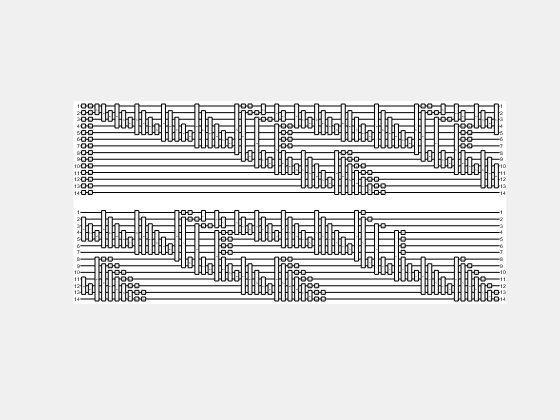

    [feasible, optimal, value] = solver_s1.verify_solution(result_qaoa, s1_optimal_val);
    fprintf('QAOA Solution - Feasible: %d, Optimal: %d, Value: %d\n', feasible, optimal, value);

#### **3.4 Custom QAOA Class**

This approach employs the custom-built QAOA class designed for greater flexibility in experimentation and tuning.

 The solver is called with three parameters: the number of quantum measurement shots (`1000`), the maximum number of classical optimization iterations (50), and the choice of classical optimizer (`'surrogateopt'`). The high number of shots helps reduce statistical noise in quantum expectation estimates, while the choice of optimizer allows testing various global search strategies. 

The `'surrogateopt'` algorithm is particularly well-suited for expensive objective functions, as it models the cost landscape to propose promising candidates efficiently.

Given the low number of iterations ('50', to reduce the time needed to perform the computation), the solver has to be run several times before obtaining the optimal solution.

Scalar objective function
Number of variables: 8
Number of integer constraints: 0
Number of linear inequality constraints: 0
Number of linear equality constraints: 0
Number of nonlinear inequality constraints: 0

F-count       Time        Best          Current         Trial
             (seconds)    Fval          Fval            type
   1         0.46      -2.1749e+02     -2.1749e+02   random 
   2         0.91      -2.3019e+02     -2.3019e+02   random 
   3         1.22      -2.3019e+02     -2.1764e+02   random 
   4         1.52      -2.4099e+02     -2.4099e+02   random 
   5         1.83      -2.4099e+02     -1.8502e+02   random 
   6         2.14      -2.9049e+02     -2.9049e+02   random 
   7         2.45      -3.1591e+02     -3.1591e+02   random 
   8         2.77      -3.1591e+02     -2.1248e+02   random 
   9         3.08      -3.1591e+02     -2.1815e+02   random 
  10         3.39      -3.1591e+02     -2.9002e+02   random 
  11         3.70      -3.1591e+02     -2.4013e+02   r

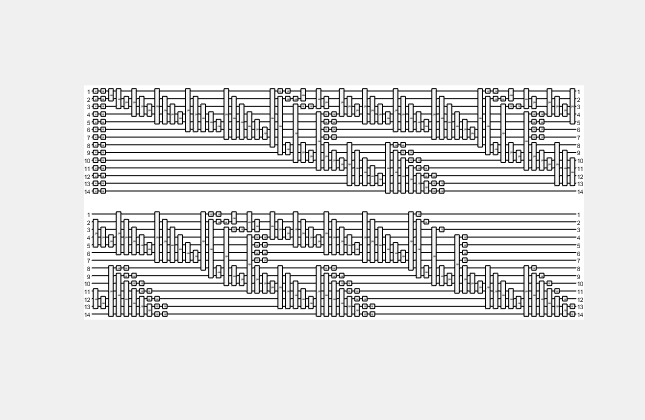

   result_QAOASolver = solver_s1.solveQAOA(1000, 50, 'surrogateopt');

   disp(result_QAOASolver);

                BestX: [14×1 double]
               Energy: -13
    OptimalParameters: [2×4 double]
            AllStates: [711×14 double]
    StateDistribution: [711×2 string]
              circuit: [1×1 quantumCircuit]



   disp('Scenario 1 - QAOA Custom Implementation');

Scenario 1 - QAOA Custom Implementation


   solver_s1.display_solution(result_QAOASolver);

Solution for Multi-Knapsack Problem:
----------------------------------
Knapsack 1 (Capacity: 5):
  Items: 2 4 
  Total Weight: 5 / 5
  Total Value: 5
  Slack: 2

Knapsack 2 (Capacity: 2):
  Items: 3 
  Total Weight: 2 / 2
  Total Value: 2
  Slack: 1

Unassigned Items: 1

Total Solution Value: 7


   [feasible, optimal, value] = solver_s1.verify_solution(result_QAOASolver, s1_optimal_val);
   fprintf('Custom QAOA Solution - Feasible: %d, Optimal: %d, Value: %d\n', feasible, optimal, value); 

Custom QAOA Solution - Feasible: 1, Optimal: 1, Value: 7


### **4. Conclusions on Knapsack Problem**

In this section, we have formulated a simple 0/1 Multi‑Knapsack instance as a QUBO problem and applied four distinct solvers to compute its optimal solution. All methods eventually found the known optimum, illustrating that each algorithm, despite its different formulation, can converge to the correct answer when given sufficient computational resources and carefully chosen parameters. In this particular case, we relied on the optimal solution found by MILP to verify when to verify when the other methods produced the optimum., but in a setting where no such information is given, a practical QAOA approach is to run the circuit several times and retain only the feasible solutions that yield the maximum profit, periodically updating as better solutions are discovered.

Because we simulated all quantum circuits classically in MATLAB, the resource requirements (circuit depth × number of shots) translate directly into classical computation time. On actual quantum hardware (QPU), deep circuits would need Quantum Error Correction, further increasing resource demands. 

Nevertheless, this example has shown:

- **How to convert a classical combinatorial problem into the QUBO (and Ising) formalism,**

- **That QAOA can be applied to resource‑allocation scenarios,**

- **The trade‑offs between exact, heuristic, and hybrid quantum‑classical methods,**

- **The importance of parameter selection in variational algorithms.**

For more complex or larger instances, one must balance solution quality against computational (or quantum) resources, tuning the parameters to reach practical performance.

## Section III - Solving a Small-Scale Max Cut Problem with QAOA

One of the most well-known benchmarks for QAOA is the Max Cut problem, which was featured in Farhi, Goldstone, and Gutmann’s original QAOA paper as a concrete example of how the algorithm can be applied to a realistic combinatorial optimization task. This problem has since become a standard test case for evaluating QAOA performance across both simulations and hardware implementations.

### **1. Problem Statement**

The Max Cut problem is defined on an undirected, weighted graph $G=\left(V,E,w\right)$

where

- $V=\left\lbrace 1,\ldotp \ldotp \ldotp ,n\right\rbrace$ is the set of vertices,

- $E\subseteq V\times V$ is the set of edges,

- $w_{ij} \ge 0$ is the weight of edge $\left(i,j\right)$.

A **cut** $\left(S,S^C \right)$ is a partition of the vertex set into two disjoint subsets $S\subset V$  and its complement $S^C =\frac{V}{S}$.  The weight of the cut is the sum of weights of edges crossing the partition:


$$\mathrm{CutWeight}\left(S\right)=\sum_{\left(i,j\right)\in E} w_{\mathrm{ij}} \;\left\lbrack x_i \not= x_j \right\rbrack ,\;$$
 

where we introduce binary variables

$x_i =\left\lbrace \begin{array}{ll}
0, & i\in S,\\
1 & i\in S^C \ldotp 
\end{array}\right.\;$�

Equivalently, using spin variables $s_i \in \left\lbrace -1,\;+1\right\rbrace$, the cut weight can be written as

$\mathrm{CutWeight}=\frac{1}{2}\;\sum_{\left(i,j\right)\in E} w_{ij} \left(1-s_i {\;s}_j \right)$.

The goal of Max Cut is to find the partition $\left(S,S^C \right)$ that **maximizes** $\mathrm{CutWeight}\left(S\right)$. In QAOA, we translate this into a cost Hamiltonian


$$C=\sum_{\left(i,j\right)\in E} w_{ij} \;\frac{\left(1-Z_i Z_j \right)}{2},$$


whose ground state (minimum energy) corresponds to the maximum cut. The QAOA circuit then alternates between evolving under this cost Hamiltonian and a transverse‑field mixer to variationally approximate its ground state.

### **2. MaxCut Problem with a 2 Nodes Graph**

To put in practice our QAOA's implementation, we consider the simplest MaxCut instance: a graph with two nodes connected by a single edge.

Consider the following undirected graph $G=\left(V,E\right)\;$where $V=\left\lbrace 1,2\right\rbrace$ and $E=\left\lbrace \left(1,2\right)\right\rbrace$.

In this case, there are only two possible partitions:


$$S=\left\lbrace 1\right\rbrace ,\;S^C =\left\lbrace 2\right\rbrace$$



$$S=\left\lbrace 2\right\rbrace ,\;S^C =\left\lbrace 1\right\rbrace$$


Both partitions yield a *cut value* of 1, as the single edge $\left(1,2\right)$ is always cut.

Let's verify if the algorithm can provide the same result.

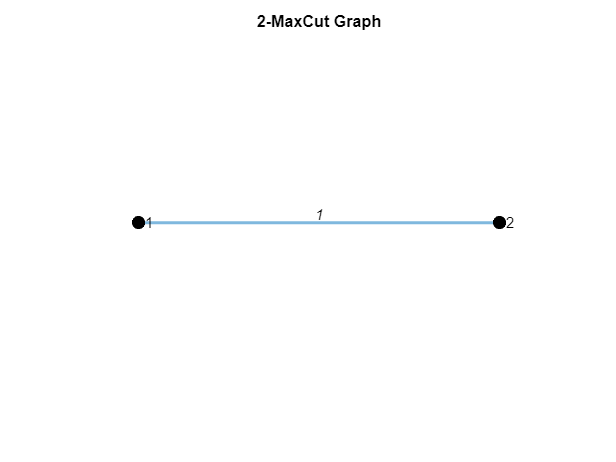

% Construct the MaxCut 2 nodes instance
s = [1];
t = [2];
weights = [1];

G = graph(s, t, weights);

% Define custom node positions for horizontal layout
nodeX = [0, 1];  % x-coordinates (left to right)
nodeY = [0, 0];  % y-coordinates (same level)

% Plot graph
figure;
p = plot(G, 'XData', nodeX, 'YData', nodeY, ...
         'EdgeLabel', G.Edges.Weight, ...
         'LineWidth', 2, ...
         'NodeColor', 'k', ...
         'MarkerSize', 8);
title('2-MaxCut Graph');
axis off;

% Calculate the QUBO matrix for MaxCut
% Q_ii = sum of weights of edges connected to node i
% Q_ij = -w_ij (negative edge weights for off-diagonal elements)
n = numnodes(G);
H = zeros(n, n);
A = adjacency(G);

% Fill in QUBO matrix based on standard formulation
for i = 1:n
    H(i,i) = sum(A(i,:)*weights);  % Diagonal: sum of connected edge weights
    for j = i+1:n
        if A(i,j) > 0  % There's an edge between nodes i and j
            % Off-diagonal: negative edge weight
            H(i,j) = -A(i,j)*weights;
            H(j,i) = H(i,j);  % Make it symmetric
        end
    end
end

fprintf(' QUBO matrix for 2-node MaxCut problem:\n');

 QUBO matrix for 2-node MaxCut problem:


disp(H);

     1    -1
    -1     1



 
 Iteration   Func-count         f(x)         Procedure
     0            1           -0.647         
     1            5           -0.647         initial simplex
     2            6           -0.647         reflect
     3            8           -0.721         reflect
     4           10           -0.794         expand
     5           11           -0.794         reflect
     6           13           -0.797         reflect
     7           14           -0.797         reflect
     8           16           -0.848         reflect
     9           18           -0.921         expand
    10           19           -0.921         reflect
    11           20           -0.921         reflect
    12           21           -0.921         reflect
    13           23           -0.953         expand
    14           25           -0.958         reflect
    15           27           -0.958         contract outside
    16           29           -0.992         reflect
    17           31           -0.99

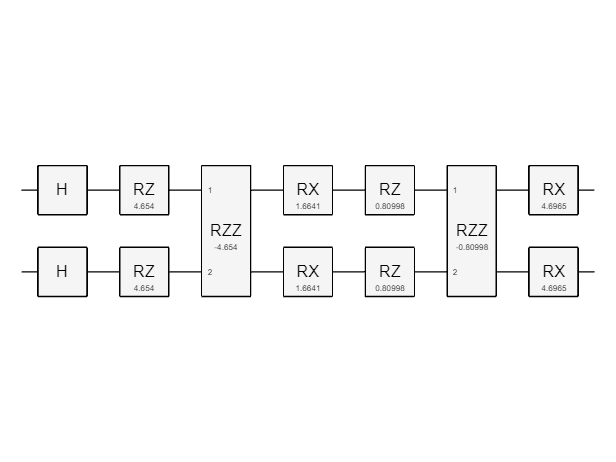

% QAOA parameters
n_layers  = 2;
init_type = 'ramp';
mixer     = 'x';
numShots  = 1000;
optimizer = 'fminsearch';
maxIter   = 100;

% Initialize QAOA solver
qaoa_maxcut_2 = QAOA(H, n_layers, init_type, mixer, numShots, maxIter, optimizer, 'max');

sol = qaoa_maxcut_2.solve();

fprintf('\nState distribution from QAOA:\n');


State distribution from QAOA:


disp(sol.StateDistribution);

    "00"    "1"  
    "01"    "492"
    "10"    "506"
    "11"    "1"  



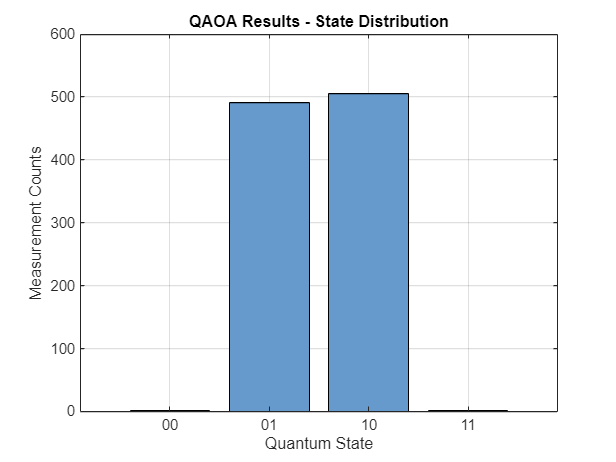

states = sol.StateDistribution(:,1);  % Get state labels ("00", "01", "10", "11")
counts = str2double(sol.StateDistribution(:,2));  % Convert counts from strings to numerical values

% Create categorical labels
state_labels = categorical(states);

% Create bar plot (histogram)
figure;
bar(state_labels, counts, 'FaceColor', [0.4 0.6 0.8]);
xlabel('Quantum State');
ylabel('Measurement Counts');
title('QAOA Results - State Distribution');
grid on;


fprintf('\nEnergy values for all possible states:\n');


Energy values for all possible states:


all_states = {'00', '01', '10', '11'};
for i = 1:length(all_states)
    state_vec = double(all_states{i}) - '0';
    x = state_vec';
    energy = x' * H * x;
    fprintf('State %s: Energy = %.4f\n', all_states{i}, energy);
    
    cut_value = 0;
    for j = 1:length(s)
        if x(s(j)) ~= x(t(j))
            cut_value = cut_value + weights(j);
        end
    end
    fprintf('Cut value = %d\n', cut_value);
end

State 00: Energy = 0.0000


Cut value = 0


State 01: Energy = 1.0000


Cut value = 1


State 10: Energy = 1.0000


Cut value = 1


State 11: Energy = 0.0000


Cut value = 0


    
% Solution validation
valid_states = [0 1; 1 0];
is_valid = ismember(sol.BestX', valid_states, 'rows');

fprintf('\nQAOA Solution:\n');


QAOA Solution:


fprintf('Best state: %s\n', num2str(sol.BestX'));

Best state: 0  1


fprintf('Energy: %.4f\n', sol.Energy);

Energy: 1.0000


% Calculate Cut Value for the found solution
x = sol.BestX;
cut_value = 0;
for j = 1:length(s)
    if x(s(j)) ~= x(t(j))
        cut_value = cut_value + weights(j);
    end
end
fprintf('Cut value: %d\n', cut_value);

Cut value: 1


if is_valid
    fprintf('Found a valid MaxCut solution!\n');
else
    fprintf('Solution is not a valid MaxCut.\n');
end

Found a valid MaxCut solution!


As it is shown by the state distribution, displayed in the histogram, QAOA's successfully identified both the optimal solutions.

### **3. MaxCut Problem with a 4 Nodes Graph**

Naturally, this problem can be scaled by considering graphs having more nodes and edges.

Let's consider a new undirected graph $G=\left(V,E\right)\;$where $V=\left\lbrace 1,2,3,4\right\rbrace$ and $E=\left\lbrace \left(1,2\right),\left(1,3\right),\left(2,4\right),\left(3,4\right)\right\rbrace$.

In this case, the optimal partitions which maximize the *cut value* are:


$$S=\left\lbrace 1,4\right\rbrace ,\;S^C =\left\lbrace 2,3\right\rbrace$$



$$S=\left\lbrace 2,3\right\rbrace ,\;S^C =\left\lbrace 1,4\right\rbrace$$


Both partitions yield a *cut value* of 4, since they are cutting all the edges of the graph.

Let's check if, once again, QAOA will provide the optimal result.

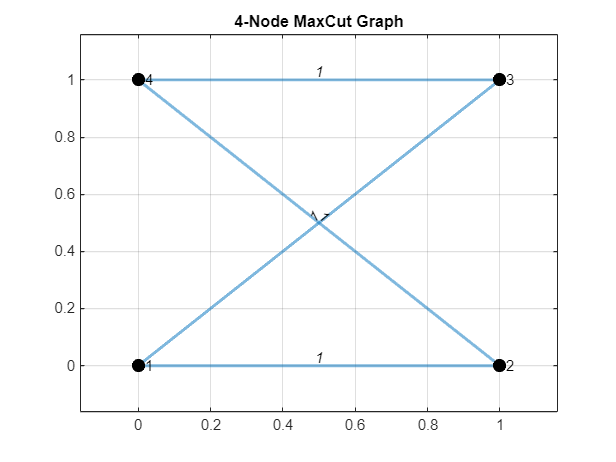

% 4-Node MaxCut Problem Instance for QAOA

% Create a 4-node graph with multiple edges
s = [1, 1, 2, 3];
t = [2, 3, 4, 4];
weights = [1, 1, 1, 1]; % Equal weights for each arch

G = graph(s, t, weights);

% Define node positions for better visualization on the graph plot
nodeX = [0, 1, 1, 0]; % x-coordinates
nodeY = [0, 0, 1, 1]; % y-coordinates

figure;
p = plot(G, 'XData', nodeX, 'YData', nodeY, ...
    'EdgeLabel', G.Edges.Weight, ...
    'LineWidth', 2, ...
    'NodeColor', 'k', ...
    'MarkerSize', 8);
title('4-Node MaxCut Graph');
grid on;


% Calculate the QUBO matrix for this MaxCut problem
n = numnodes(G);
H = zeros(n, n);
A = adjacency(G);

% Diagonal: Sum of weights connected to node
% Off-diagonal: Negative of edge weights
for i = 1:n
    H(i,i) = sum(A(i,:)); % Sum of connected edge weights
    for j = i+1:n
        if A(i,j) > 0
            H(i,j) = -A(i,j); % Negative edge weight
            H(j,i) = H(i,j);  % Make it symmetric
        end
    end
end

fprintf('QUBO Matrix for 4-Node MaxCut Problem:\n');

QUBO Matrix for 4-Node MaxCut Problem:


disp(H);

     2    -1    -1     0
    -1     2     0    -1
    -1     0     2    -1
     0    -1    -1     2



 
 Iteration   Func-count         f(x)         Procedure
     0            1           -1.844         
     1            7            -1.98         initial simplex
     2            9           -2.174         expand
     3           11           -2.174         contract inside
     4           12           -2.174         reflect
     5           14           -2.308         expand
     6           15           -2.308         reflect
     7           17           -2.308         contract outside
     8           19           -2.632         expand
     9           21           -2.986         expand
    10           22           -2.986         reflect
    11           24           -3.224         expand
    12           25           -3.224         reflect
    13           26           -3.224         reflect
    14           27           -3.224         reflect
    15           28           -3.224         reflect
    16           30           -3.224         contract inside
    17           31  

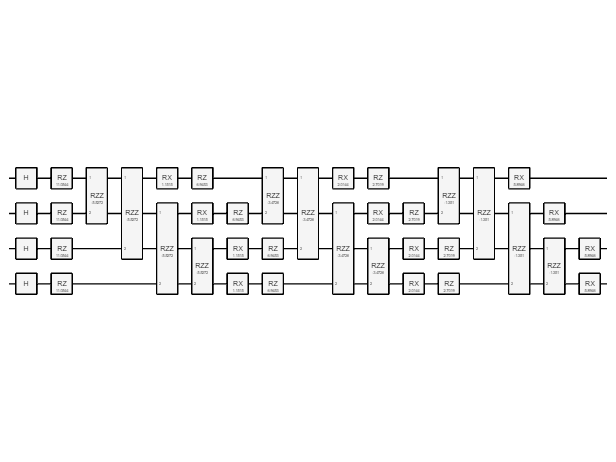

% QAOA parameters
n_layers = 3;       
init_type = 'ramp'; 
mixer = 'x';        
numShots = 1000;
optimizer = 'fminsearch'; 
maxIter = 100;

% Initialize QAOA solver
qaoa_maxcut_4 = QAOA(H, n_layers, init_type, mixer, numShots, maxIter, optimizer, 'max');

sol_maxcut_4 = qaoa_maxcut_4.solve();


fprintf('\nState distribution from QAOA measurements:\n');


State distribution from QAOA measurements:


disp(sol_maxcut_4.StateDistribution);

    "0000"    "56" 
    "0001"    "15" 
    "0010"    "24" 
    "0011"    "27" 
    "0100"    "16" 
    "0101"    "28" 
    "0110"    "374"
    "0111"    "1"  
    "1000"    "15" 
    "1001"    "360"
    "1010"    "23" 
    "1011"    "1"  
    "1100"    "15" 
    "1101"    "1"  
    "1110"    "1"  
    "1111"    "43" 



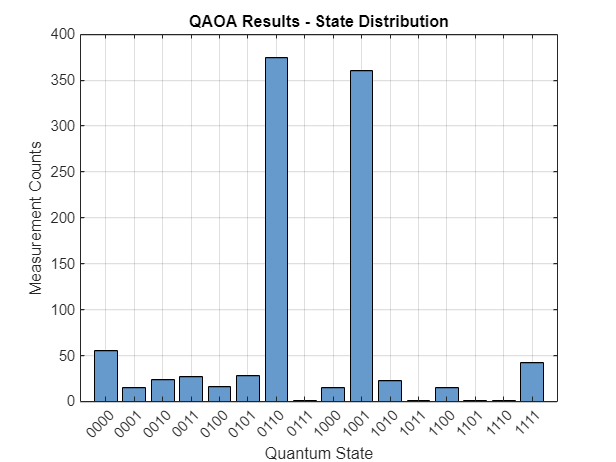

states = sol_maxcut_4.StateDistribution(:,1);  % Get state labels
counts = str2double(sol_maxcut_4.StateDistribution(:,2));  % Convert counts from strings to numerical values

% Create categorical labels
state_labels = categorical(states);

% Create bar plot (histogram)
figure;
bar(state_labels, counts, 'FaceColor', [0.4 0.6 0.8]);
xlabel('Quantum State');
ylabel('Measurement Counts');
title('QAOA Results - State Distribution');
grid on;

fprintf('\nBest solution found:\n');


Best solution found:


fprintf('State: %s\n', num2str(sol_maxcut_4.BestX'));

State: 0  1  1  0


fprintf('Energy: %.4f\n', sol_maxcut_4.Energy);

Energy: 4.0000



% Calculate the actual cut value
x = sol_maxcut_4.BestX;
cut_value = 0;
for j = 1:length(s)
    if x(s(j)) ~= x(t(j))
        cut_value = cut_value + weights(j);
    end
end
fprintf('Cut value: %d (out of maximum: 4)\n', cut_value);

Cut value: 4 (out of maximum: 4)



if cut_value == 4
    fprintf('\nQAOA found an optimal MaxCut solution!\n');
else
    fprintf('\nQAOA found a suboptimal solution.\n');
end


QAOA found an optimal MaxCut solution!


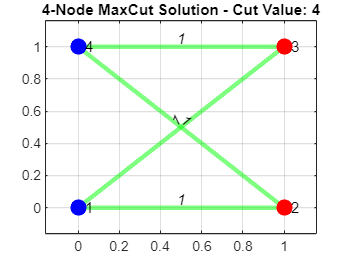


% Visualize the solution by coloring nodes
figure;
nodeColors = zeros(n, 3);
for i = 1:n
    if sol_maxcut_4.BestX(i) == 1
        nodeColors(i,:) = [1 0 0]; % Red for partition 1
    else
        nodeColors(i,:) = [0 0 1]; % Blue for partition 0
    end
end

p = plot(G, 'XData', nodeX, 'YData', nodeY, ...
    'EdgeLabel', G.Edges.Weight, ...
    'LineWidth', 2, ...
    'NodeColor', nodeColors, ...
    'MarkerSize', 10);
title(['4-Node MaxCut Solution - Cut Value: ' num2str(cut_value)]);
grid on;

% Calculate cut edges and highlight them
cut_edges = [];
for i = 1:length(s)
    if sol_maxcut_4.BestX(s(i)) ~= sol_maxcut_4.BestX(t(i))
        cut_edges = [cut_edges; i];
    end
end


highlight(p, s(cut_edges), t(cut_edges), 'EdgeColor', 'g', 'LineWidth', 3);

The dominance of the states `0110` and `1001` in the final state distribution confirms QAOA’s ability to identify optimal solutions. 

Suboptimal states arise due to finite sampling noise or imperfect parameter optimization but are heavily suppressed with a reasonable choice of the number of collected samples.

### **4. Conclusions on MaxCut Problems**

In this section, we explored the QAOA algorithm solving the MaxCut problem.

 Using our MATLAB `QAOA` class, we tested the algorithm on small graphs (2-node and 4-node) and successfully found the optimal cuts in both cases. This shows that QAOA, even in its basic form, can solve problems relying on the quantum-classical approach.

When comparing QAOA to classical methods, a few things wil stood out. Classical brute-force methods *guarantee* the optimal cut but quickly become impractical for larger graphs: imagine checking every possible split for a 20-node graph; that’s over a million possibilities! 

On the other hand, classical approximation methods, like the Goemans-Williamson algorithm, work faster but settle for "good enough" solutions. 

QAOA sits somewhere in between. It doesn’t promise perfection, but it leverages quantum mechanics to explore many solutions at once, while the classical optimizer refines the parameters iteratively. For small graphs, this hybrid approach works well, and it’s flexible—you can create bigger graphs, increase the circuit depth (`n_layers`) and tune the other parameters in order to obtain optimal solutions also in these computationally complex settings, though this comes at the cost of longer runtimes or noisier outcomes on real quantum hardware.

## `Acknowledgments`

### `1 Resources`

Marco Venere, *“Quantum Computing - A Practical Perspective”, Politecnico di Milano*.

### `2 Articles `

[1] E. Fahri, J. Goldstone, S. Gutmann (2014) ["A Quantum Approximate Optimization Algorithm"](https://doi.org/10.48550/arXiv.1411.4028)

[2] F. Glover , G. Kochenberger , Y. Du, (2018) ["A Tutorial on Formulating and Using QUBO Models"](https://doi.org/10.48550/arXiv.1811.11538)

[3] A. Awasthi, F. Bar, J. Doetsch, H. Ehm, M. Erdmann, M. Hess, J. Klepsch, P. A. Limacher, A. Luckow, C. Niedermeier, L. Palackal, R. Pfeiffer, P. Ross, H. Safi, J. Schonmeier-Kromer, O. von Sicard, Y. Wenger, K. Wintersperger, S. Yarkoni (2023) ["Quantum Computing Techniques for Multi-Knapsack Problems"](https://doi.org/10.48550/arXiv.2301.05750)

[4] E. Guney , J. Ehrenthal, T. Hanne, (2025) ["Quantum Approaches to the 0/1 Multi-Knapsack Problem"](https://www.scitepress.org/Papers/2025/133877/133877.pdf)

### `3 Websites `

[MathWorks - Quadratic Unconstrained Binary Optimization(QUBO)](https://mathworks.com/help/matlab/qubo.html)

[MathWorks - What Is a QUBO Problem?](https://mathworks.com/help/matlab/math/what-is-a-qubo.html)

[MathWorks - Verify Optimality by Solving QUBO as MILP](https://mathworks.com/help/matlab/math/solve-qubo-using-milp.html)

[MathWorks - Solve Max-Cut Problem Using QAOA](https://mathworks.com/help/matlab/math/max-cut-with-qaoa.html) - `(Source of Fig. 1)`